# Live App

Get Weather Forecast

apiKey ="b1b15e88fa797225412429c1c50c122a1";

% Define the location for which you want the weather forecast
city = "Muenchen,DE";

% Create the URL for the API call
url = sprintf("http://samples.openweathermap.org/data/2.5/forecast?q=%s&appid=%s", city, apiKey);
 

% Send the web request to the OpenWeatherMap API
response = webread(url);

% Assuming "response" is the struct obtained from the OpenWeatherMap API
data = parseForecast(response.list);
T = struct2table(data);
TT = table2timetable(T);
 

Fit Model

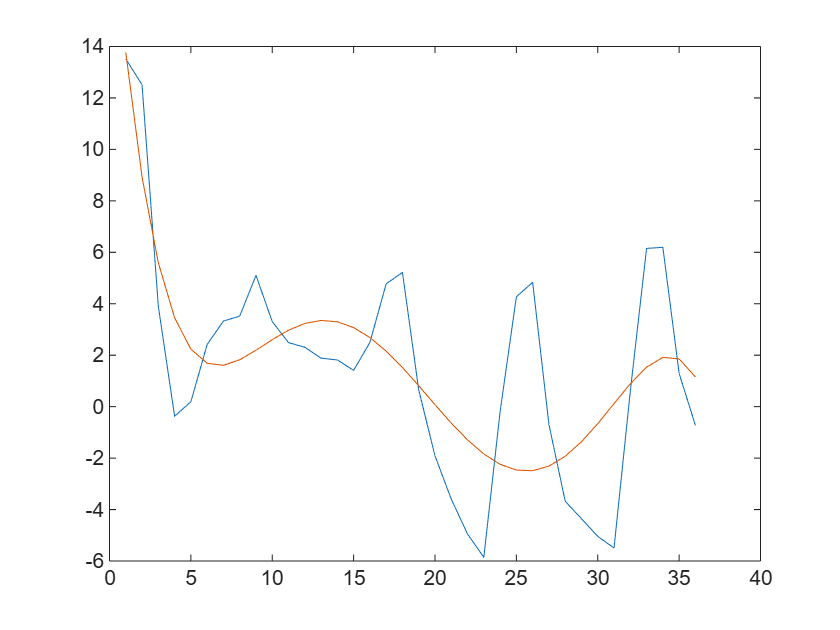

n = 5;
X = linspace(1,height(TT),height(TT));
y = TT.temperature;
p = polyfit(X,y,n);
y1 = polyval(p,X);
plot(X,y,X,y1)

function forecastData = parseForecast(responseList)
    % Initialize an array of structs to hold the parsed forecast data
    forecastData = struct("date", {}, "temperature", {}, "weather", {}, "clouds", {}, "wind", {}, "details", {});

    % Loop through each entry in the responseList cell array
    for i = 1:length(responseList)
        % Get the current forecast struct
        forecastStruct = responseList{i};

        % Extract the date and time of the forecast
        forecastData(i).date = datetime(forecastStruct.dt, "ConvertFrom", "posixtime");

        % Extract main forecast data like temperature
        forecastData(i).temperature = forecastStruct.main.temp - 273.15;

        % Extract weather conditions
        forecastData(i).weather = forecastStruct.weather(1).main;

        % Extract cloud data
        forecastData(i).clouds = forecastStruct.clouds.all;

        % Extract wind data
        forecastData(i).wind = forecastStruct.wind.speed;

        % Extract additional details if needed
        forecastData(i).details = forecastStruct.weather(1).description;
    end
end